# OTFS Modulation — Sending a Text Message

**Goal:** Send the text message "Hello World This Is Ammar" through an OTFS (and OFDM, for comparison) link over a simulated high-mobility multipath channel, and recover the exact same text at the receiver. This proves OTFS can carry real information end-to-end, not just a test pilot.

**Steps we are breaking this into:**

- Text -> Bits -> QPSK Symbols

- Place symbols into the Delay-Doppler (DD) grid

- Embed a pilot symbol (+ guard band) into the grid for channel sounding

- OTFS modulate (and OFDM modulate, for comparison)

- Pass through the multipath + Doppler channel + noise

- Demodulate back to the DD domain

- Estimate the channel from the pilot (Hdd, chanEst)

- Equalize the data using the channel estimate

- QPSK demodulate recovered symbols -> bits

- Bits -> text -> compare recovered message to the original

We are currently through Step 5 (modulation). This notebook documents what we've done and understood so far.

## Parameters

M = 64;        % delay bins
N = 30;        % Doppler bins
padLen = 10;   % zero-pad length (must exceed channel delay spread)
padType = 'ZP';

## Step 1: Text -> Bits -> QPSK Symbols

Convert each character to ASCII, then to 8-bit binary, then flatten into one long bit vector.

msg = 'Hello World This Is Ammar';
msgBits = reshape(dec2bin(uint8(msg),8).' - '0', [], 1);

length(msg)        % 25 characters

ans = 25

length(msgBits)     % 25 * 8 = 200 bits

ans = 200

Pair up consecutive bits (2 bits per QPSK symbol) and modulate. `reshape` fills column-by-column: bits (1,2) -> col 1, bits (3,4) -> col 2, etc.

Xdata = reshape(msgBits, 2, []);
symbols = pskmod(Xdata, 4, pi/4, InputType="bit");

length(symbols)   % 200/2 = 100 QPSK symbols

ans = 100

## Step 2: Place Symbols into the Delay-Doppler Grid

Grid capacity is M*N = 1920 symbols. Our message only needs 100, so the rest of the grid stays zero (unused capacity, not a problem for this test).

Xdd = zeros(M, N);
Xdd(1:length(symbols)) = symbols;   % column-major fill -> lands in columns 1-2

nnz(Xdd)     % 100 nonzero symbols placed

ans = 100

## Step 3: Embed Pilot for Channel Sounding

We are placing data in (1,16) location but in current case data is filled in col major that's why that location is empty what if that was not empty then in that case, you'd need to reserve the pilot's cell (and guard band) first, then fill data only into the remaining free cells, skipping over the reserved region. Basically: decide where the pilot goes before filling data, and make sure the data-fill logic avoids that spot.

pilotBin = floor(N/2)+1;
Xdd(1, pilotBin) = exp(1i*pi/4);
nnz(Xdd);

## Step 4: OTFS & OFDM Modulation

**For OTFS side **

- Xdd 64×30 → IZT (IFFT over Doppler axis, per row) → still 64×30 (delay-time domain)

- Add ZP: 10 zero rows appended per column → 74×30

- Serialize column-by-column → 2220×1 vector = txOTFS

**For OFDM side **

- Xdd treated as frequency-domain grid, 64 subcarriers × 30 OFDM symbols

- Per column: IFFT (size M=64) → time-domain OFDM symbol

- Add CP or ZP (padLen=10) → 74 samples per symbol

- Serialize column-by-column → 2220×1 = txOFDM

txOTFS = helperOTFSmod(Xdd, padLen, padType);
txOFDM = ofdmmod(Xdd, M, padLen);

length(txOTFS)   % (M+padLen)*N = 2220

ans = 2220

length(txOFDM)    % 2220

ans = 2220

## Step 4 — Visualization

Compare how each scheme spreads the same input grid into time.

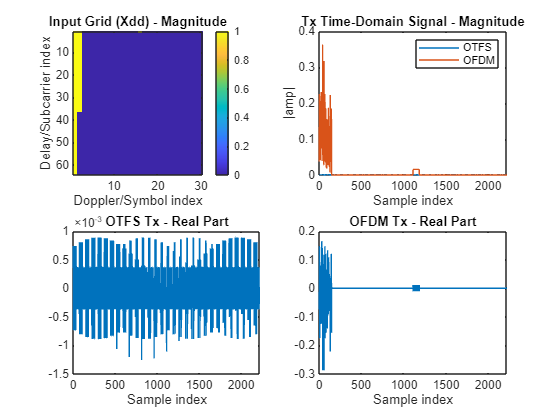

figure('Name','Step 4: OTFS vs OFDM Modulation');

subplot(2,2,1);
imagesc(abs(Xdd));
title('Input Grid (Xdd) - Magnitude');
xlabel('Doppler/Symbol index'); ylabel('Delay/Subcarrier index'); colorbar;

subplot(2,2,2);
plot(abs(txOTFS)); hold on; plot(abs(txOFDM));
legend('OTFS','OFDM');
title('Tx Time-Domain Signal - Magnitude');
xlabel('Sample index'); ylabel('|amp|');

subplot(2,2,3);
plot(real(txOTFS));
title('OTFS Tx - Real Part');
xlabel('Sample index');

subplot(2,2,4);
plot(real(txOFDM));
title('OFDM Tx - Real Part');
xlabel('Sample index');

**What this shows:**

- **(a) Input Grid:** yellow strip in columns 1-2 = our 100 data symbols; small mark near row 1, column 16 = the pilot. Rest is zero.

- **(b) Tx magnitude overlay:** OFDM shows a concentrated burst in the first ~150 samples (only columns 1-2 had data, and OFDM's IFFT acts per-column independently) then silence, with a small blip near sample 1150 (the pilot's column). OTFS looks flat/small but is nonzero across **all** 2220 samples.

- **(c) OTFS real part:** continuous oscillation across the whole signal -- the Zak transform's Doppler-axis IFFT smears every grid symbol across all time samples, regardless of which column it came from.

- **(d) OFDM real part:** energy concentrated only where the source data was (first ~150 samples), flat elsewhere -- OFDM keeps each column's data localized to its own time slot.

**Key takeaway:** this is the core structural difference between the two schemes -- OTFS spreads every symbol across the entire transmission in time, while OFDM keeps each symbol's energy localized to one time slot. This is why OTFS is resilient to localized/burst channel problems that would otherwise wipe out an OFDM symbol.

## Step 5 — Channel

Same 3-path channel as our very first example — direct path + 2 delayed/Doppler-shifted scatterers, plus AWGN at 40dB SNR. Both `txOTFS` and `txOFDM` go through the identical channel so the comparison is fair.

%% Step 5: Channel (Delay + Doppler + AWGN)

df = 15e3;
fc = 5e9;
fsamp = M*df;
Meff = M + padLen;
T = Meff/(M*df);

chanParams.pathDelays   = [0  5   8  ];
chanParams.pathGains    = [1  0.7 0.5];
chanParams.pathDopplers = [0 -3   5  ];
chanParams.pathDopplerFreqs = chanParams.pathDopplers * 1/(N*T);

SNRdB = 40;

dopplerOutOTFS = dopplerChannel(txOTFS, fsamp, chanParams);
chOutOTFS = awgn(dopplerOutOTFS, SNRdB, 'measured');

dopplerOutOFDM = dopplerChannel(txOFDM, fsamp, chanParams);
chOutOFDM = awgn(dopplerOutOFDM, SNRdB, 'measured');

length(chOutOTFS)

ans = 2228

length(chOutOFDM)

ans = 2228

Plots

%% Step 5 — Visualization

t_tx = 0:length(txOTFS)-1;
t_rx = 0:length(chOutOTFS)-1;

figure('Name','Step 5: Before vs After Channel');

subplot(2,2,1);
plot(t_tx, abs(txOTFS));
title('OTFS Tx (before channel)'); xlabel('Sample'); ylabel('|amp|');

subplot(2,2,2);
plot(t_rx, abs(chOutOTFS));
title('OTFS Rx (after channel + noise)'); xlabel('Sample'); ylabel('|amp|');

subplot(2,2,3);
plot(t_tx, abs(txOFDM));
title('OFDM Tx (before channel)'); xlabel('Sample'); ylabel('|amp|');

subplot(2,2,4);
plot(t_rx, abs(chOutOFDM));

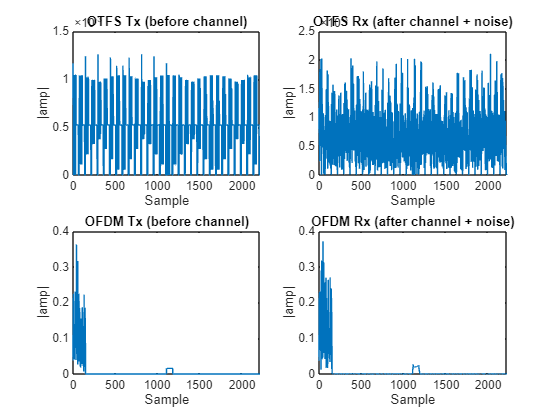

title('OFDM Rx (after channel + noise)'); xlabel('Sample'); ylabel('|amp|');

**(a) OTFS Tx (before channel):** Time-domain waveform showing energy spread continuously across all 2220 samples, oscillating between roughly 0 and 1.5×10⁻³ — the Zak transform (Doppler-axis IFFT) mixes every DD grid symbol into every time sample, so even though only 2 columns + 1 pilot had data, the output has no silent regions.

**(b) OTFS Rx (after channel + noise):** Same overall dense/continuous pattern as (a), but amplitude range widens (up to ~2×10⁻³) and the waveform is visibly noisier/more jagged. This is the sum of 3 delayed, Doppler-shifted, scaled copies of (a) overlapping everywhere, plus AWGN — since OTFS already had energy spread across the full signal, multipath doesn't create new bursts, it just adds variability on top of the existing dense waveform.

**(c) OFDM Tx (before channel):** Energy concentrated almost entirely in the first ~150 samples (from the 2 data-filled grid columns), with one small isolated blip near sample 1150 (the pilot's column). Everything else is exactly zero — OFDM's per-column IFFT keeps each symbol's energy localized to its own time slot.

**(d) OFDM Rx (after channel + noise):** Same two regions of activity as (c) — the initial burst and the pilot blip — but each is slightly widened/smeared, since the 3 multipath delays (0, 5, 8 samples) shift and overlap copies of the original burst on top of each other. The silent regions in between stay essentially flat/quiet, since multipath can't create energy where the transmitted signal had none.

## Step 6 - Demodulation

numSamps = Meff*N;   % 2220, one frame length

rxOTFS = chOutOTFS(1:numSamps);
Ydd = helperOTFSdemod(rxOTFS, M, padLen, 0, padType);

rxOFDM = chOutOFDM(1:numSamps);
Yofdm = ofdmdemod(rxOFDM, M, padLen);

size(Ydd)  

ans =     64    30


size(Yofdm)

ans =     64    30


%% Step 6 — Visualization

figure('Name','Step 6: Original vs Demodulated DD Grids');

subplot(2,2,1);
imagesc(0:N-1, 0:M-1, abs(Xdd));
title('Original Grid (Xdd)');
xlabel('Doppler index'); ylabel('Delay index'); colorbar;

subplot(2,2,2);
imagesc(0:N-1, 0:M-1, abs(Ydd));
title('OTFS Demodulated (Ydd)');
xlabel('Doppler index'); ylabel('Delay index'); colorbar;

subplot(2,2,3);
imagesc(0:N-1, 0:M-1, abs(Xdd));
title('Original Grid (Xdd)');
xlabel('Doppler index'); ylabel('Delay index'); colorbar;

subplot(2,2,4);
imagesc(0:N-1, 0:M-1, abs(Yofdm));
title('OFDM Demodulated (Yofdm)');

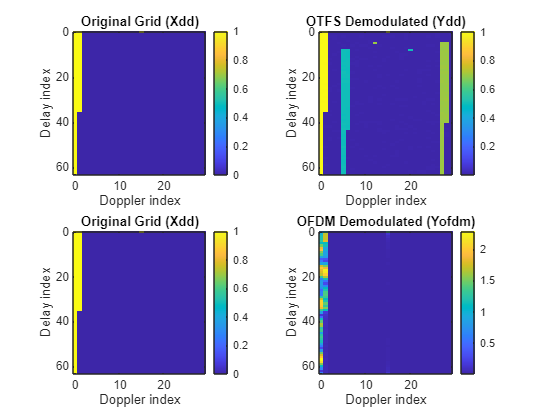

xlabel('Doppler index'); ylabel('Delay index'); colorbar;

**(a) Original Grid (Xdd):** the input grid we built — 100 data symbols packed into columns 1-2, one pilot at (1,16). Sharp, clean, mostly zero elsewhere.

**(b) OTFS Demodulated (Ydd):** should look like a **smeared/blurred version** of (a) — instead of sharp data confined to columns 1-2 and one crisp pilot dot, you'll see the same content spread into multiple nearby positions, since the 3-path channel convolves everything in the DD domain (recall: each impulse becomes 3 shifted+scaled copies). Data in columns 1-2 should now show echoes at columns 6-7 and 9-10 roughly (shifted by paths' delay/Doppler offsets), and the pilot should show its familiar 3-peak pattern near column 16.

**(c) Original Grid (Xdd):** same as (a), repeated for direct side-by-side comparison with OFDM's output.

**(d) OFDM Demodulated (Yofdm):** this will look **very different** from (a) — OFDM demodulation converts back to a frequency-domain-per-symbol view, not the same DD-domain structure. Since our data was placed assuming DD-domain semantics (not native OFDM subcarrier/symbol semantics), `Yofdm` won't visually resemble `Xdd` at all — it's the channel's effect on each OFDM subcarrier per symbol, which is fundamentally a different domain than what we put in. This mismatch is expected and important: it's exactly why OFDM needs proper per-subcarrier channel estimation (step 7) before this data becomes meaningful, whereas OTFS's structure lets us directly interpret `Ydd`'s smearing pattern as the channel's DD fingerprint.

## Step 7 -- Channel Estimation

% --- OTFS: estimate Hdd from the embedded pilot ---
Es = mean(abs(pskmod(0:3,4,pi/4).^2));
n0 = Es/(10^(SNRdB/10));

Hdd_full = Ydd * conj(Xdd(1,pilotBin)) / (abs(Xdd(1,pilotBin))^2 + n0);

% Restrict search to near the pilot's own column — avoids picking up
% echoes from the data symbols sitting in columns 1-2
dopplerGuard = 8;
searchRows = 1:(1+padLen);
searchCols = max(1,pilotBin-dopplerGuard):min(N,pilotBin+dopplerGuard);

Hdd = zeros(M,N);
Hdd(searchRows, searchCols) = Hdd_full(searchRows, searchCols);

[lp,vp] = find(abs(Hdd) >= 0.05);
chanEst.pathGains    = diag(Hdd(lp,vp));
chanEst.pathDelays   = lp - 1;
chanEst.pathDopplers = vp - pilotBin;

% --- OFDM: needs its own pilot-sounding frame (pilots on ALL subcarriers/symbols) ---
txPilotOFDM = ofdmmod(exp(1i*pi/4)*ones(M,N), M, padLen);
dopplerPilotOFDM = dopplerChannel(txPilotOFDM, fsamp, chanParams);
chPilotOFDM = awgn(dopplerPilotOFDM, SNRdB, 'measured');
YofdmPilot = ofdmdemod(chPilotOFDM(1:numSamps), M, padLen);

Hofdm = YofdmPilot * conj(exp(1i*pi/4)) / (abs(exp(1i*pi/4))^2 + n0);

chanEst.pathDelays     % should be ~[0 5 8]

ans =      5
     0
     8


chanEst.pathDopplers    % should be ~[0 -3 5]

ans =     -3
     0
     5


abs(chanEst.pathGains)  % should be ~[1 0.7 0.5]

ans =     0.6977
    1.0002
    0.5018



size(Hofdm)   % 64 x 30

ans =     64    30


## Step 8 Equalization


% --- OTFS: time-domain LMMSE using estimated channel matrix G ---
G = getG(M,N,chanEst,padLen,padType);
y_otfs = ((G'*G)+n0*eye(Meff*N)) \ (G'*rxOTFS);
Xhat_otfs = helperOTFSdemod(y_otfs,M,padLen,0,padType);

% --- OFDM: single-tap FDE using Hofdm ---
Xhat_ofdm = conj(Hofdm) .* Yofdm ./ (abs(Hofdm).^2+n0);

size(Xhat_otfs)   % 64 x 30

ans =     64    30


size(Xhat_ofdm) 

ans =     64    30


## Step 9 Recovery

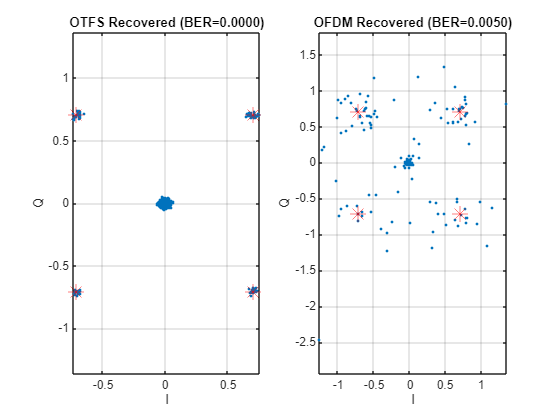

% --- Constellation comparison ---
figure('Name','Step 9: Recovered Constellations');
subplot(1,2,1);
plot(real(Xhat_otfs(:)), imag(Xhat_otfs(:)), '.'); hold on;
plot(real(pskmod(0:3,4,pi/4)), imag(pskmod(0:3,4,pi/4)), 'r*','MarkerSize',12);
title(sprintf('OTFS Recovered (BER=%.4f)', berOTFS));
xlabel('I'); ylabel('Q'); axis equal; grid on;

subplot(1,2,2);
plot(real(Xhat_ofdm(:)), imag(Xhat_ofdm(:)), '.'); hold on;
plot(real(pskmod(0:3,4,pi/4)), imag(pskmod(0:3,4,pi/4)), 'r*','MarkerSize',12);
title(sprintf('OFDM Recovered (BER=%.4f)', berOFDM));
xlabel('I'); ylabel('Q'); axis equal; grid on;

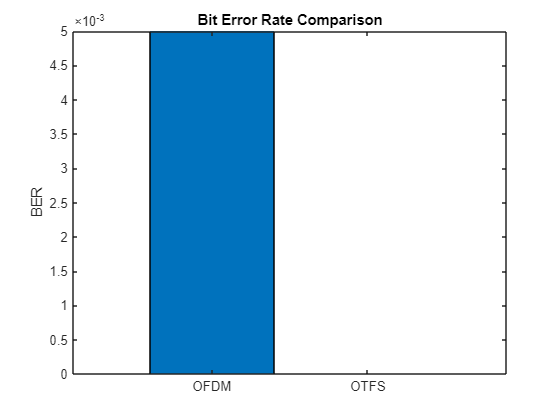


% --- BER bar chart ---
figure('Name','Step 9: BER Comparison');
bar(categorical({'OTFS','OFDM'}), [berOTFS berOFDM]);
title('Bit Error Rate Comparison');
ylabel('BER');

bitsOTFS = pskdemod(Xhat_otfs, 4, pi/4, OutputType="bit", OutputDataType="double");
bitsOFDM = pskdemod(Xhat_ofdm, 4, pi/4, OutputType="bit", OutputDataType="double");

bitsOTFS_flat = bitsOTFS(:);
bitsOFDM_flat = bitsOFDM(:);

recoveredBitsOTFS = bitsOTFS_flat(1:length(msgBits));
recoveredBitsOFDM = bitsOFDM_flat(1:length(msgBits));

msgOTFS = char(bin2dec(char(reshape(recoveredBitsOTFS,8,[]).' + '0')).');
msgOFDM = char(bin2dec(char(reshape(recoveredBitsOFDM,8,[]).' + '0')).');

berOTFS = mean(recoveredBitsOTFS ~= msgBits);
berOFDM = mean(recoveredBitsOFDM ~= msgBits);

fprintf('Original message : %s\n', msg);

Original message : Hello World This Is Ammar


fprintf('OTFS recovered    : %s   (BER = %.4f)\n', msgOTFS, berOTFS);

OTFS recovered    : Hello World This Is Ammar   (BER = 0.0000)


fprintf('OFDM recovered    : %s   (BER = %.4f)\n', msgOFDM, berOFDM);

OFDM recovered    : Hello Wor|d This Is Ammar   (BER = 0.0050)
